FEPubsAna

Shuai Yang

2023/7/17

pubnum =      2   NaN   NaN   NaN   NaN   NaN
     1   NaN   NaN   NaN   NaN   NaN
     1   NaN   NaN   NaN   NaN   NaN
    12   NaN   NaN   NaN   NaN   NaN
     9   NaN   NaN   NaN   NaN   NaN
    60   NaN   NaN   NaN   NaN   NaN
     2   NaN   NaN   NaN   NaN   NaN
    12   NaN   NaN   NaN   NaN   NaN
     3   NaN   NaN   NaN   NaN   NaN
    37   NaN   NaN   NaN   NaN   NaN


pubnum =      2     0   NaN   NaN   NaN   NaN
     1     1   NaN   NaN   NaN   NaN
     1     1   NaN   NaN   NaN   NaN
    12     1   NaN   NaN   NaN   NaN
     9     1   NaN   NaN   NaN   NaN
    60     2   NaN   NaN   NaN   NaN
     2     0   NaN   NaN   NaN   NaN
    12     0   NaN   NaN   NaN   NaN
     3     1   NaN   NaN   NaN   NaN
    37     0   NaN   NaN   NaN   NaN


pubnum =      2     0     0   NaN   NaN   NaN
     1     1     6   NaN   NaN   NaN
     1     1     6   NaN   NaN   NaN
    12     1    30   NaN   NaN   NaN
     9     1     0   NaN   NaN   NaN
    60     2     2   NaN   NaN   NaN
     2     0     4   NaN   NaN   NaN
    12     0     0   NaN   NaN   NaN
     3     1     0   NaN   NaN   NaN
    37     0     0   NaN   NaN   NaN


pubnum =      2     0     0     0   NaN   NaN
     1     1     6     3   NaN   NaN
     1     1     6     3   NaN   NaN
    12     1    30     0   NaN   NaN
     9     1     0     0   NaN   NaN
    60     2     2     0   NaN   NaN
     2     0     4     0   NaN   NaN
    12     0     0     0   NaN   NaN
     3     1     0     0   NaN   NaN
    37     0     0     0   NaN   NaN


pubnum =      2     0     0     0     0   NaN
     1     1     6     3     0   NaN
     1     1     6     3     0   NaN
    12     1    30     0     0   NaN
     9     1     0     0     0   NaN
    60     2     2     0     4   NaN
     2     0     4     0     0   NaN
    12     0     0     0     0   NaN
     3     1     0     0     0   NaN
    37     0     0     0     1   NaN


pubnum =      2     0     0     0     0     0
     1     1     6     3     0     0
     1     1     6     3     0     0
    12     1    30     0     0     0
     9     1     0     0     0     0
    60     2     2     0     4     0
     2     0     4     0     0     0
    12     0     0     0     0     0
     3     1     0     0     0     0
    37     0     0     0     1     0


mymap =     0.9000    0.9447    0.9741
    0.8965    0.9427    0.9732
    0.8929    0.9408    0.9723
    0.8894    0.9388    0.9714
    0.8859    0.9369    0.9704
    0.8824    0.9349    0.9695
    0.8788    0.9330    0.9686
    0.8753    0.9310    0.9677
    0.8718    0.9291    0.9668
    0.8682    0.9271    0.9659


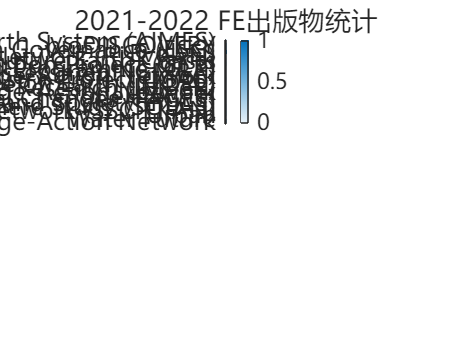



dirTxt = 'C:\Users\yssam\OneDrive\文档\崖州湾科技城管理局\Future Earth\FE Publication\FE Publications 2021-2022.txt';
dirSave = fileparts(dirTxt);

S = readlines(dirTxt);

emptyLineTF = strcmp(S,"");% find empty lines
S = S(~emptyLineTF); % 删除emptyLines
% Global Reserch Network
GRN = S(9:end);

JournalTF = strcmp(GRN,"Peer-reviewed journals/proceedings");
k = find(JournalTF);
k_names = k-1;
GRNnames = GRN(k_names);

% pubData = struct('GRNname',[],'pubs',[],'journals',[],'Books',[],...
%     'Policy',[],'Other',[],'Conferences',[]);
pubData = struct([]);

for i = 1:numel(k_names)
    pubData(i).GRNname = GRNnames(i);
    if i == numel(k_names)
        pubData(i).pubs = GRN(k_names(i)+1:end);
    else
        pubData(i).pubs = GRN(k_names(i)+1:k_names(i+1)-1);
    end
end

% pubStyle = {"Peer-reviewed journals/proceedings","Books/Chapters","Policy Briefs",...
%     "International Conferences",'Other'};




for iGRN = 1:numel(pubData)
    GRN_pub = pubData(iGRN).pubs;
    lineStrNum = strlength(GRN_pub);
    styleIdx = lineStrNum<35;
    styleTag = find(styleIdx);
    styles = GRN_pub(styleTag);
    % pat = lettersPattern;
    % styles = extract(styles,pat)
    styles = strip(styles);
    p = [".","/","-"," "];
    styles = replace(styles,p,"");

    for i= 1:numel(styleTag)
        fieldname = styles(i);
        fieldname = char(fieldname);
        fieldname  = fieldname(1:4);
        if i == numel(styleTag)

            pubData(iGRN). (fieldname) = GRN_pub(styleTag(i)+1:end);
        else
            pubData(iGRN). (fieldname)= GRN_pub(styleTag(i)+1:styleTag(i+1)-1);
        end
    end
end

fieldNames = fieldnames(pubData);
pubnum = NaN(numel(pubData),6);
n = 0;
for i = 3:8
    n = n+1;
a = {pubData.(fieldNames{i})};
pubnum(:,n) = cellfun(@numel,a)
end
numOrder = [1,2,5,3,4,6];
pubnum1 = pubnum(:,numOrder); 
pubnum2 = [];
pubnum2(:,1:3) = pubnum1(:,1:3);
pubnum2(:,4) = sum(pubnum1(:,4:end),2);


pubStyle = {'Journals/proceedings 文章','Policy Briefs 政策建议','Books/chapters 书籍','Others 其它'};
% [mymap,~,~] = brewermap(96,'RdBu');% blue 2 red colormap
% mymap = flip(mymap,1);
mymap = colormap('sky')
cdata = pubnum2;
xvalues = pubStyle;
yvalues = GRNnames;
h = heatmap(xvalues,yvalues,cdata,'Colormap',mymap);
% h.CellLabelColor = 'none';
% h.GridVisible = 'off';
% h2.CellLabelFormat = '%0.1f';
h.ColorScaling ='scaledcolumns';
h.Title = '2021-2022 FE出版物统计';

h.XLabel = '发表类型 ';
h.YLabel = 'GRN 研究网络';
h.FontName = '微软雅黑';
h.FontSize = 12;

figure,
tiledlayout(4,1);
nexttile
bar(1:22,sum(cdata,2))

nexttile
bar(1:22,cdata(:,1))
nexttile
bar(1:22,cdata(:,2))
nexttile
bar(1:22,cdata(:,3))
nexttile
bar(1:22,cdata(:,4))
